# COVID19 Data Analysis

Robert Gregg

University of Pittsburgh

April 3rd 2020

## Import the data

The data orgininates from the [HGIS Lab](https://hgis.uw.edu/virus/) at the University of Washinton

% Specify location and name of the file
filename = 'virus.csv';

% Read the data into memory
opts=detectImportOptions(filename);
opts.VariableNamesLine = 1;
virusRaw = readtable(filename,opts,'ReadVariableNames', true);

head(virusRaw,10)

ans = 10×352 table
          datetime             anhui         beijing       chongqing       fujian         gansu        guangdong       guangxi       guizhou        hainan        hebei       heilongjiang       henan        hongkong          hubei             hunan       neimenggu       jiangsu        jiangxi        jilin        liaoning       macau       ningxia       qinghai      shaanxi       shandong       shanghai        shanxi        sichuan       taiwan       tianjin

## Clean the data for analysis

%The list of numbers represent aggregated-active-recovered-death
%Convert the strings into vectors of numbers
virus = varfun(@(x) sscanf(x{1},'%f'),virusRaw,'GroupingVariables','datetime','OutputFormat','cell');

%If an entry is empty, then the location has no reported cases
virus(cellfun(@isempty,virus)) = {[0,0,0,0]};

%Let's just look at the aggregated cases for now
cases = cellfun(@(x) x(1),virus);

## Plotting a few countries

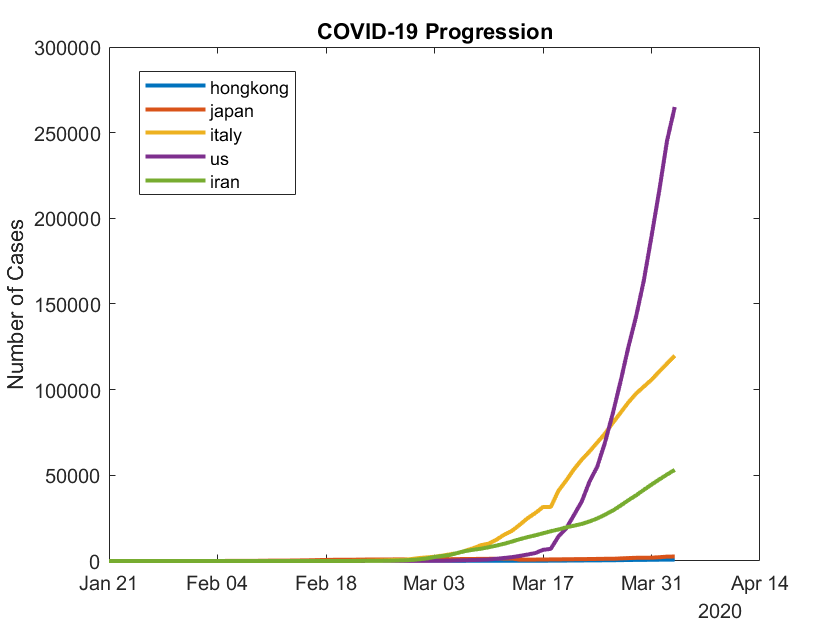

%Picking some country names
countries = {'hongkong','southkorea','japan','us','italy','iran'};

%Find where they are located in the data
countryNames = virusRaw.Properties.VariableNames(2:end);
countryIdx = ismember(countryNames,countries);

%Generate a nice plot
fig1 = plot(virusRaw.datetime,cases(:,countryIdx),'linewidth',2);
ylabel('Number of Cases')
title('COVID-19 Progression')
legend(countryNames(countryIdx),'location','best')

%Prevent scientific notation on y axis 
ax = ancestor(fig1, 'axes');
ax{1}.YAxis.Exponent = 0;
ytickformat('%.0f')

## Fitting a Model to Disease Progression

%Choose a country to model
myCountry = 'us';
myCountryIdx = ismember(countryNames,myCountry);

%Choose a model, here I chose a logistic growth model
logisticfit = @(L,k,t0,x) L./(1+exp(-k.*(x-t0)));

% Extract the data for your country
timePast = datenum(virusRaw.datetime) - min(datenum(virusRaw.datetime));
caseNumbers = cases(:,myCountryIdx);

% Define a start points for parameters
xGuess = [1500000 .4 70]; 

%Fit the model with the fit() function
fitfun = fittype( logisticfit );
[fittedCurve,goodnessOfFit] = fit(timePast,caseNumbers,fitfun,'StartPoint',xGuess)

fittedCurve =      General model:
     fittedCurve(x) = L./(1+exp(-k.*(x-t0)))
     Coefficients (with 95% confidence bounds):
       L =    3.83e+05  (3.669e+05, 3.991e+05)
       k =        0.26  (0.2521, 0.2678)
       t0 =       69.94  (69.58, 70.29)

goodnessOfFit = struct with fields:
           sse: 1.7323e+08
       rsquare: 0.9993
           dfe: 71
    adjrsquare: 0.9993
          rmse: 1.5620e+03


## Plot the Model Against the Data

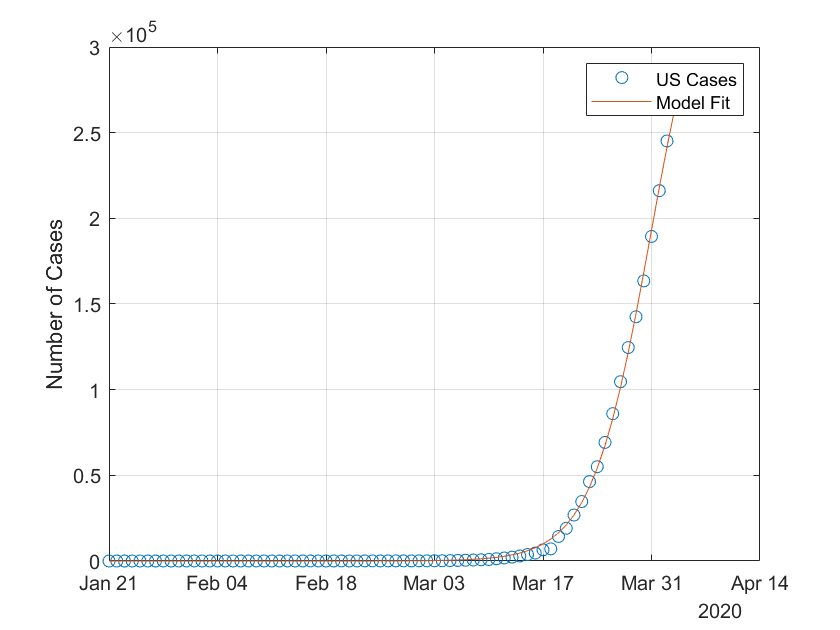

% Plot results
scatter(virusRaw.datetime, caseNumbers, 'o','DisplayName','US Cases')
hold on
plot(virusRaw.datetime,fittedCurve(timePast),'DisplayName','Model Fit')
box on
legend
ylabel('Number of Cases')
grid on
hold off

## Extrapolate the Model

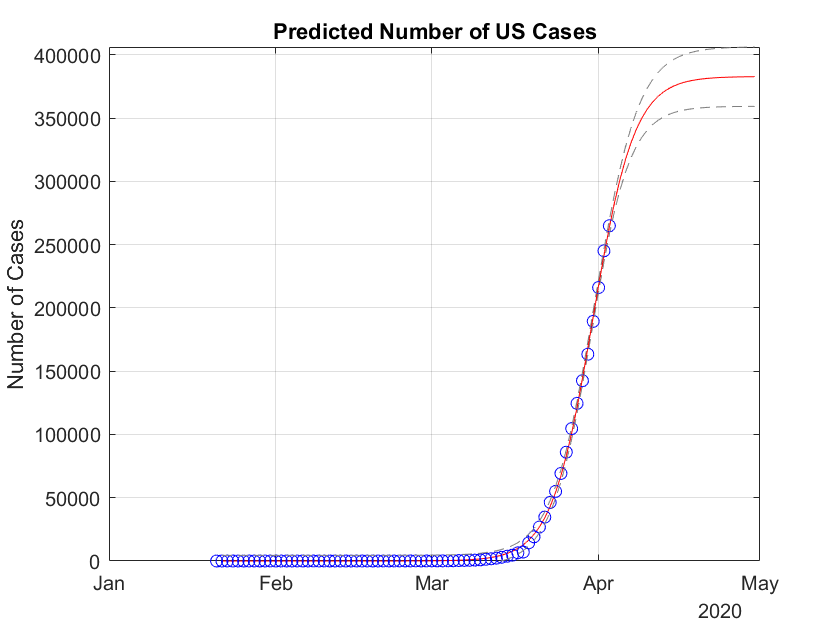

%Plot 100 days past Jan-21 (first recorded datapoint)
daysPast = 1:100;
%Calculate the number of cases
predExtrap = fittedCurve(daysPast);

%Convert dats past to dates
extrapDates = datetime(datevec( min(datenum(virusRaw.datetime))+daysPast ));

%Calculate prediction bounds
predictBounds = predint(fittedCurve,daysPast,0.95,'observation','on');

fig3 = plot(extrapDates,predExtrap,'r');

%Plot the data points
hold on
scatter(virusRaw.datetime, caseNumbers, 'bo','DisplayName','US Cases')

%Plot the prediction bounds
plot(extrapDates,predictBounds,'--','Color',[0.5,0.5,0.5]);
ylabel('Number of Cases')
title('Predicted Number of US Cases')
ylim([0 inf])
grid on

%Remove scientific notation
ax = ancestor(fig3, 'axes');
ax.YAxis.Exponent = 0;
ytickformat('%.0f')